usage: teamwork for week 9

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.5.1

clear all; close all; clc

**1. 已知实验数据如下**

**   |**$$t_i$$** | 19   | 25    | 31    | 38    | 44   |**

**   |**$$y_i$$**| 19.0 | 32.3 | 49.0 | 73.3 | 97.8|**

**用最小二乘法采用模型函数**$$y=a+bt^2$$**拟合上述数据。 **

**   (1) 请推导**$$a, b$$**的求解公式。**

**   (2) 根据(1)的结果， 编写脚本， 确定**$$a$$**与**$$b$$**, 并计算均方误差RMSE**

解：

（1）


$$当y=a+bt^2\\
求解a，b使得残差平方和\ S最小\\
即为求解\min \ S(a, b) = \sum_{i=1}^{n}[y_i-(a+bt_i^2)]^2\\
令S_i=[y_i-(a+bt_i^2)]^2,\ \frac{\partial S_i}{\partial a}=-2[y_i-(a+bt_i^2)],\ \frac{\partial S_i}{\partial b}=-2t_i^2[y_i-(a+bt_i^2)]\\
当\frac{\partial S}{\partial a}=0，\frac{\partial S}{\partial b}=0时，残差平方和\ S最小\\
\Rightarrow \frac{\partial S}{\partial a}=\sum_{i=1}^{n}(y_i-a-bt_i^2)=\bar{y} - a-b\bar{t^2}=0\\
\Rightarrow \frac{\partial S}{\partial b}=\sum_{i=1}^{n}(y_i-a-bt_i^2)t_i^2=\bar{yt^2}-a\bar{t^2}-b\bar{t^4}=0\\
\Rightarrow \pmatrix {1 & \bar{t^2} \cr \bar{t^2} & \bar{t^4}} \pmatrix{a \cr b}=\pmatrix{\bar{y} \cr \bar{yt^2}}
求解该线性方程组即可得到a,b.$$


（2）

clear all; close all; clc
t_1 = [19 25 31 38 44];
y_1 = [19.0 32.3 49.0 73.3 97.8];
%对应参数的求解
para_1 = [1, mean(t_1.^2); mean(t_1.^2), mean(t_1.^4)] \ [mean(y_1); mean(y_1.*t_1.^2)]

para_1 =     0.9726
    0.0500


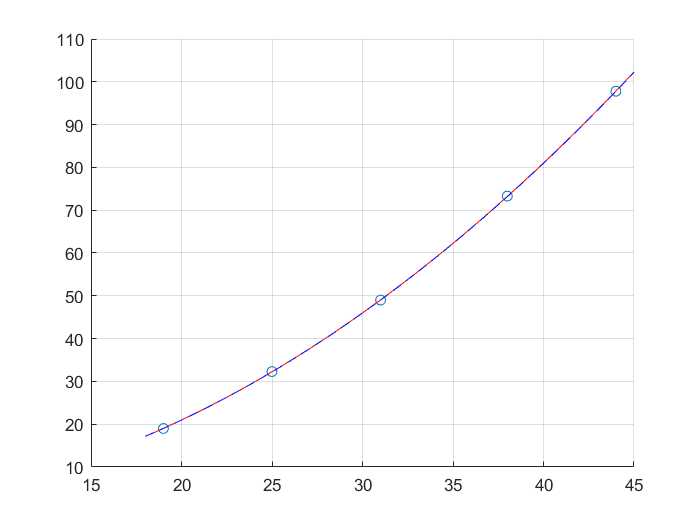

%作出原数据点及拟合曲线
scatter(t_1, y_1)
hold on
plot(18:0.5:45, (para_1(1) + para_1(2).*(18:0.5:45).^2),'r')
hold off
grid on

得到的表达式为$y = 0.9726+0.05t^2$，拟合曲线如图所示。

SSE_1 = sum((para_1(1) + para_1(2).*t_1.^2 - y_1).^2);
DFE_1 = length(t_1) - 2;
RMSE_1 = sqrt(SSE_1 / DFE_1)

RMSE_1 = 0.0708

计算得到均方误差RMSE为0.0708.

**2. 有等距取值点上的25个观测值y如下**

clear all; close all; clc
t_2 = 1:25;
y_2 = [5.0291 6.5099 5.3666 4.1272 4.2948...
       6.1261 12.5140 10.0502 9.1614 7.5677...
       7.2920 10.0357 11.0708 13.4045 12.8415...
       11.9666 11.0765 11.7774 14.5701 17.0440...
       17.0398 15.9069 15.4850 15.5112 17.6572]

y_2 =     5.0291    6.5099    5.3666    4.1272    4.2948    6.1261   12.5140   10.0502    9.1614    7.5677    7.2920   10.0357   11.0708   13.4045   12.8415   11.9666   11.0765   11.7774   14.5701   17.0440   17.0398   15.9069   15.4850   15.5112   17.6572


**   (1) 用直线模型**$$y(t)=a_0+a_1t$$**拟合数据，并绘出残差**$$y(t_k)-y_k$$**. 你一定可以观察到，有一个数据点处的残差特别大。它可能是一个离群点。**

解：

直线模型的两个线性独立函数为$1，t$

F_2_1 = {@(t) 1, @(t) t};
A_2_1 = normal_equation(t_2, y_2, F_2_1)

A_2_1 =     4.0127
    0.5326


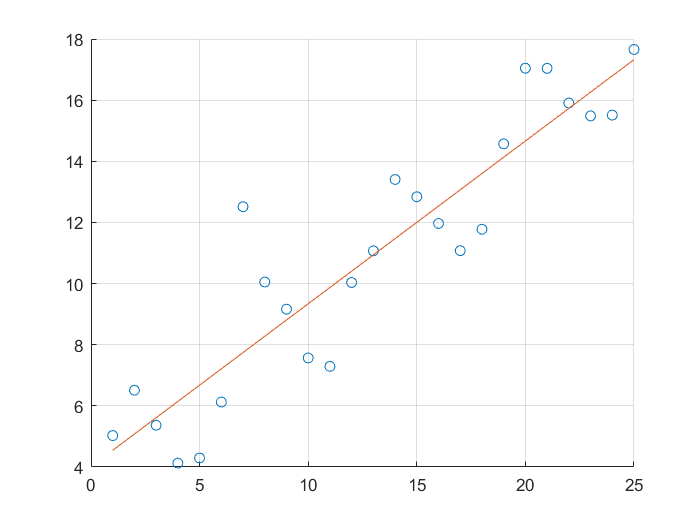

scatter(t_2, y_2)
hold on
plot(t_2, fit_equation(t_2, F_2_1, A_2_1))
hold off
grid on

得到直线模型为$y(t)=4.0127+0.5326t$

绘出残差$|y(t_k)-y_k|$

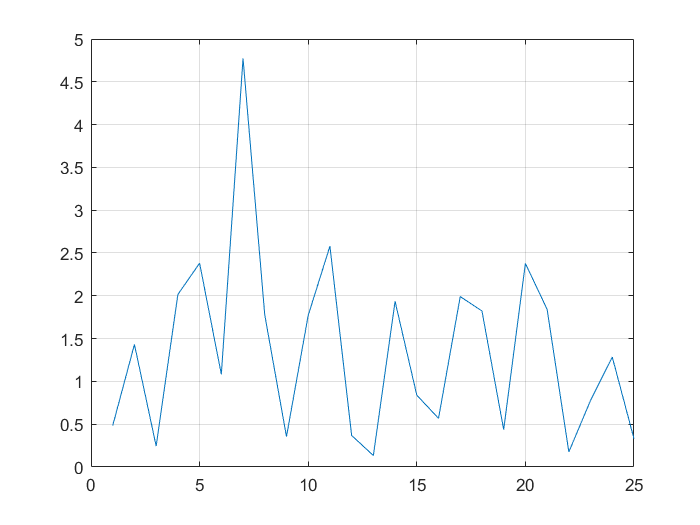

plot(t_2, abs(fit_equation(t_2, F_2_1, A_2_1) - y_2))
grid on

可以观察到当$t=7$时残差达到了4.773，可能是一个离群点。

**   (2) 剔除离群点，再用直线拟合，并再次绘出残差。你在残差曲线里看出了什么模式了吗？**

t_2(7) = [];
y_2(7) = [];
plot(t_2, y_2)
A_2_2 = normal_equation(t_2, y_2, F_2_1)

A_2_2 =     3.5008
    0.5563


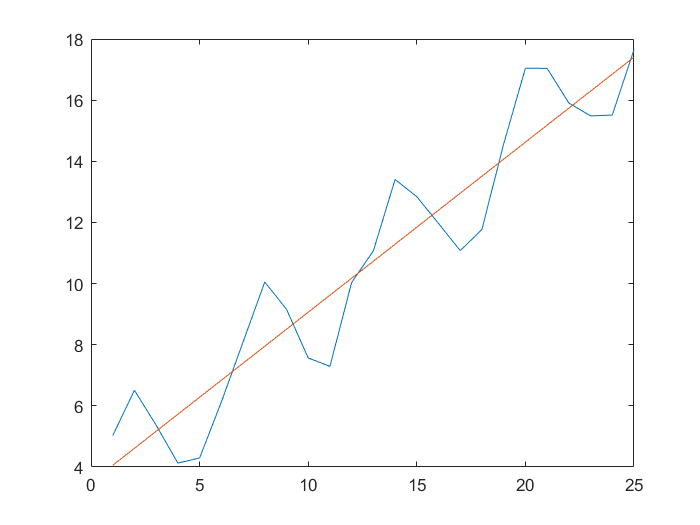

hold on
plot(t_2, fit_equation(t_2, F_2_1, A_2_2))
hold off

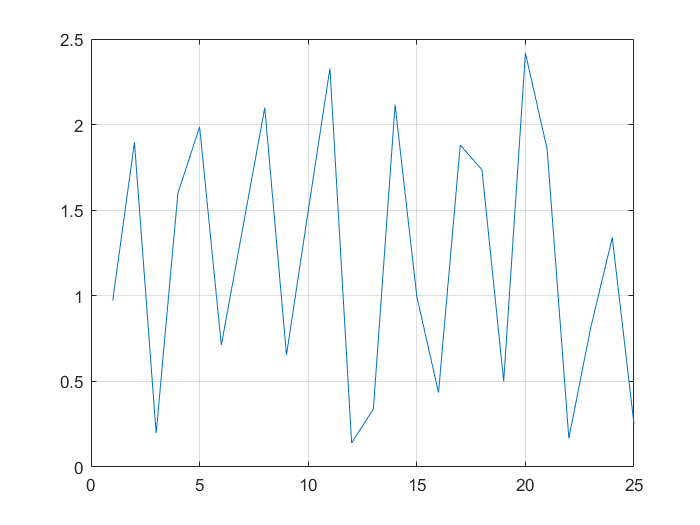

plot(t_2, abs(fit_equation(t_2, F_2_1, A_2_2) - y_2))
grid on

残差曲线呈周期性的震荡。

**   (3) 不考虑离群点，用下列模型拟合所给数据**$$y(t)=\beta_1+\beta_2 t+\beta_3 \sin t$$**，并绘出拟合曲线。**

拟合曲线模型的独立函数为$1,t,sin(t)$

F_2_3 = {@(t) 1, @(t) t, @(t) sin(t)};
A_2_3 = normal_equation(t_2, y_2, F_2_3)

A_2_3 =     3.1536
    0.5869
    1.9733


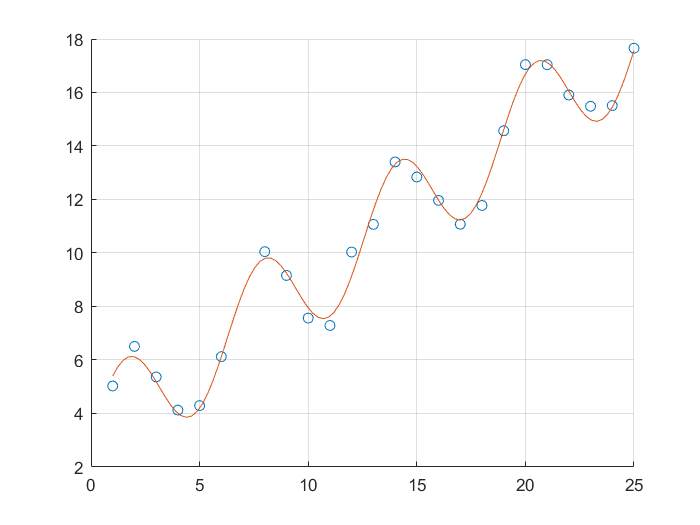

scatter(t_2, y_2)
hold on
t_2_3 = linspace(1,25);
plot(t_2_3, fit_equation(t_2_3, F_2_3, A_2_3))
hold off
grid on

得到拟合函数为$y(t)=3.1536+0.5869t+1.9733sin(t)$，拟合效果基本较好。

**3. 考虑如下的估计式**


$$   $$
   \prod_{p<P}\left(1+\frac{1}{p}\right)\approx C_1+C_2\ln P
   $$$$


**其中**$$P$$**为素数， **$$p$$**为所有不大于**$$P$$**的素数。 编写脚本， 从素数列表中的数据计算这些乘积，并由此做拟合确定**$$C_1$$**和**$$C_2$$**.   **

**   (提示： 可用`primes(103)`来产生素数序列)**

解：

线性最小二乘拟合的独立函数为$1，ln(P)$

clear all; close all; clc
n_3 = 103;
P_3 = primes(n_3);
%计算乘积
y_3 = zeros(size(P_3));
for i = 1:length(P_3)
    y_3(i) = prod(1+1./primes(P_3(i)));
end
scatter(P_3, y_3)
hold on
F_3 = {@(P) 1, @(P) log(P)};
A_3 = normal_equation(P_3, y_3, F_3)

A_3 =     0.9055
    0.9061


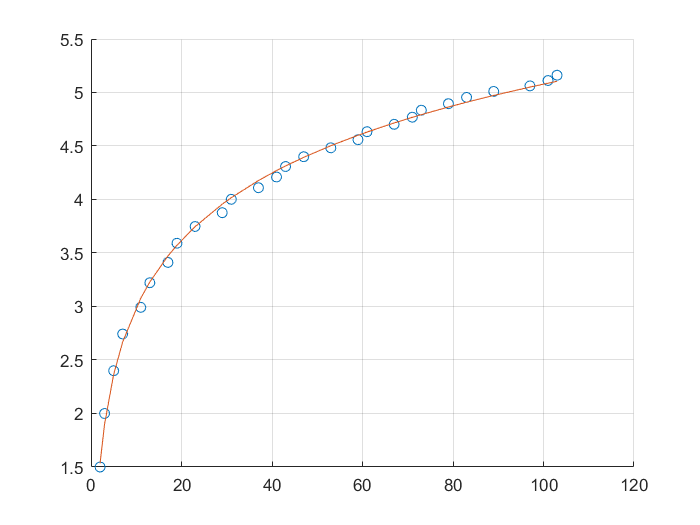

plot(P_3, fit_equation(P_3, F_3, A_3))
hold off
grid on

得到拟合函数为$y(P)=0.9055+0.9061ln(P)$

**4. 产生11个数据点，**$ $t_k=(k-1)/10$$**, **$$y_k=\text{erf}(t_k)$$** (`erf`为误差函数), **$$k=1,\cdots,11$$**.   **

**   (1) 分别用1-10阶多项式对数据进行最小二乘法拟合。 在拟合区间之间， 对拟合多项式的值与**$$\text{erf}(t)$$**的实际函数值进行比较。 问： 最大误差与多项式阶次有何关系？**

解：

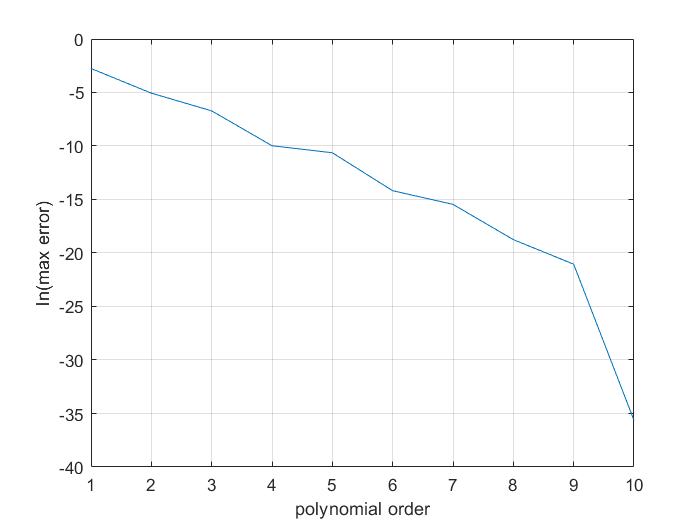

clear all; close all; clc
t_4 = 1:11;
t_4 = (t_4 - 1) ./ 10;
y_4 = erf(t_4);
e_4_1 = zeros(10, 1);
for i = 1:10
    e_4_1(i) = max(abs(polyval(polyfit(t_4, y_4, i), t_4) - y_4));
end
% 显示最大误差
plot(1:10, log(e_4_1)) %通过对最大误差取ln，使得高阶多项式数值较小的最大误差变化趋势得以显现
xlabel("polynomial order")
ylabel("ln(max error)")
grid on

disp(e_4_1(10))%显示多项式拟合的最小的误差

   3.3307e-16



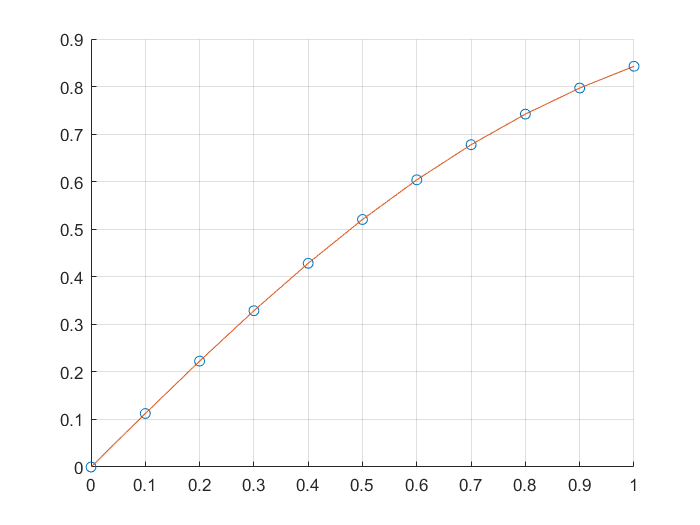


% 函数点以及拟合曲线
scatter(t_4, y_4)
hold on
plot(t_4, polyval(polyfit(t_4, y_4, 10), t_4))
hold off
grid on

从图中可以发现，最大误差随多项式阶次增大而降低。10阶多项式的误差为3.3307e-16。

**   (2) 由于**$$\text{erf}(x)$$**是奇函数， 即**$$\text{erf}(-x)=-\text{erf}(x)$$**, 因此采用**$$t$$**的奇次幂的组合拟合数据更为合理**


$$   $$
   \text{erf}(t)\approx c_1t+c_2t^3 + \cdots + c_nt^{2n-1}
   $$ $$


**   问：拟合区间中的误差与**$$n$**之间的关系。**

e_4_2 = zeros(10, 1);
F_4_2 = {};
for i = 1:10
    f = @(t) t.^(2*i-1);
    F_4_2{i} = f;
    e_4_2(i) = max(abs(fit_equation(t_4, F_4_2, normal_equation(t_4, y_4, F_4_2)) - y_4));
end

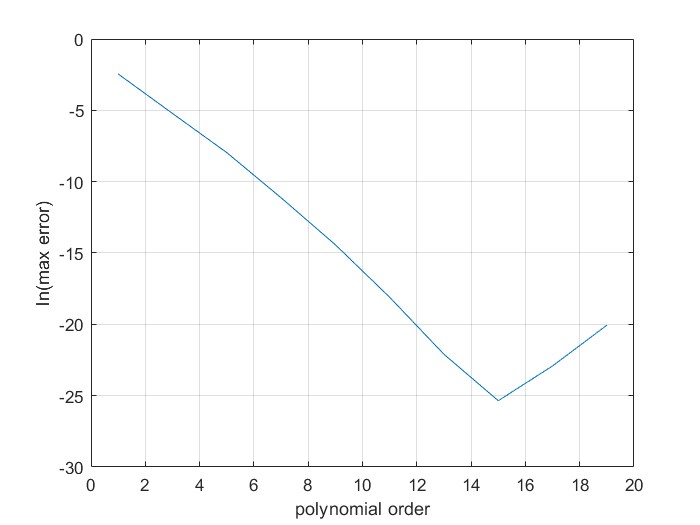

% 显示最大误差
plot(2*(1:10) - 1, log(e_4_2))
xlabel("polynomial order")
ylabel("ln(max error)")
grid on


disp(min(e_4_2))%显示奇次幂拟合的最小的误差

   9.7678e-12




% 函数点以及拟合曲线
scatter(t_4, y_4)
hold on
plot(t_4, fit_equation(t_4, F_4_2(1:8), normal_equation(t_4, y_4, F_4_2(1:8))))
hold off
grid on

从图中可以发现，最大误差在最高次从1-15的奇数次幂拟合下随n的增大而降低，而在最高次15-19的奇数次幂拟合下随n增大而增大。最大误差最小的15阶奇数次幂多项式为9.7678e-12。

**   (3) 事实上， 多项式不能较好近似**$$\text{erf}(t)$$**, 因为随**$$t$$**变大， 多项式值无界， 而**$$\text{erf}(t)$**趋于1， 所以， 请对同一组数据采用如下拟合模型**


$$   $$
   \text{erf}(t)\approx c_1+e^{-t^2}(c_2+c_3z+c_4z^2+c_5z^3)
   $$$$


**   其中**$$z=1/(1+t)$$**. 请讨论该模型的误差与多项式模型的比较。**

拟合函数的独立函数为$1,e^{-t^2},\frac{e^{-t^2}}{1+t},\frac{e^{-t^2}}{(1+t)^2},\frac{e^{-t^2}}{(1+t)^3}$

e_negt_square = @(t) exp(-t.^2);
z = @(t) 1./(1+t);
F_4_3 = {@(t) 1, e_negt_square,...
    @(t) e_negt_square(t).*z(t),...
    @(t) e_negt_square(t).*z(t).^2,...
    @(t) e_negt_square(t).*z(t).^3};
e_4_3 = max(abs(fit_equation(t_4, F_4_3, normal_equation(t_4, y_4, F_4_3)) - y_4))

e_4_3 = 2.6711e-05

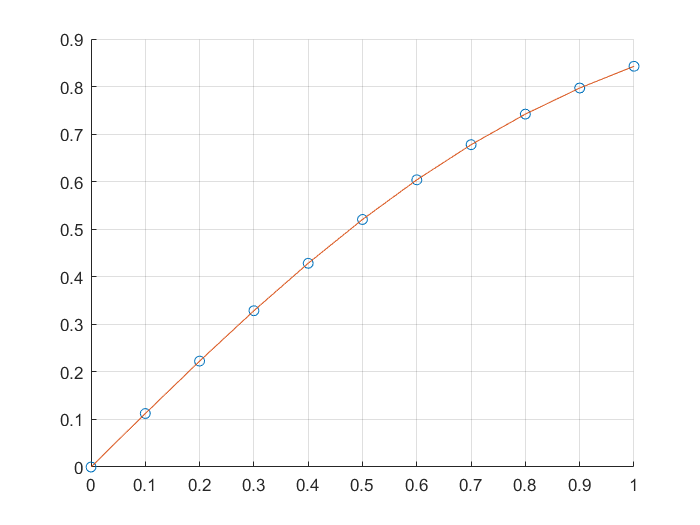

% 函数点以及拟合曲线
scatter(t_4, y_4)
hold on
plot(t_4, fit_equation(t_4, F_4_3, normal_equation(t_4, y_4, F_4_3)))
hold off
grid on

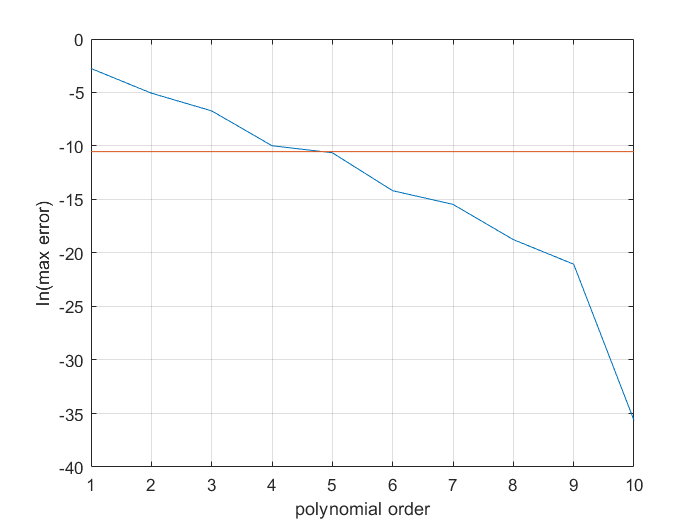

%通过对最大误差取ln，使得高阶多项式数值较小的最大误差变化趋势得以显现
plot(1:10, log(e_4_1), 1:10, log(e_4_3)*ones(1,10)) %通过对最大误差取ln，使得高阶多项式数值较小的最大误差变化趋势得以显现
xlabel("polynomial order")
ylabel("ln(max error)")
grid on

该模型的误差接近五阶多项式模型的误差。

**5. 分别用3阶多项式和5阶多项式拟合数据。 数据由如下函数**


$$   $$
   y = \sin\left(\frac{1}{x+0.2}\right)+0.2x
   $$$$


**   加上一些随机噪声生成， 随机噪声的分布是标准差为0.06的正态分布。 请在同张图上画出两条拟合曲线， 并讨论拟合结果。  **

**   提示： 使用`randn`产生随机噪声， 使用`polyfit`做多项式拟合。**

解：

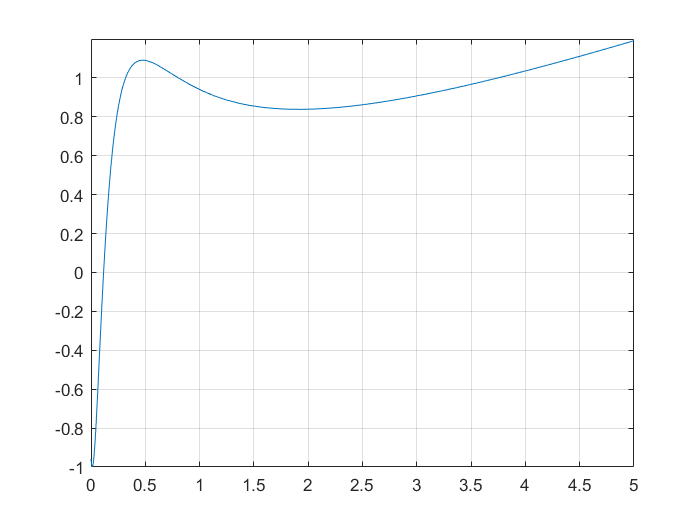

clear all; close all; clc
f_5 = @(x) sin(1./(x + 0.2)) + 0.2*x;
fplot(f_5, [0, 5])%
grid on

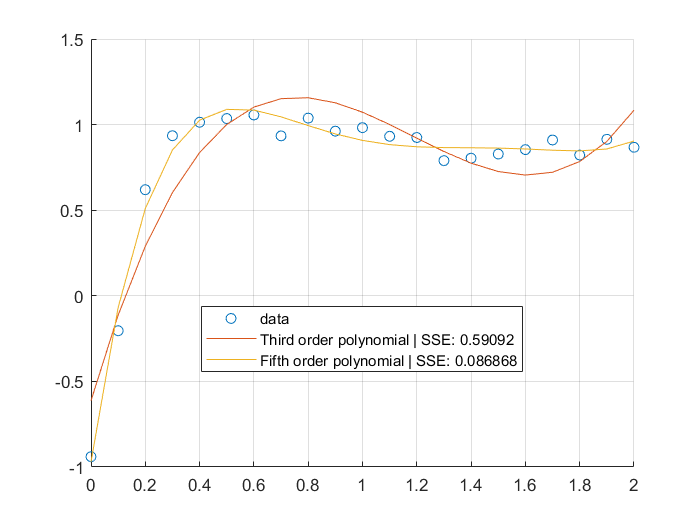

x_5 = 0:0.1:2;
y_5 = f_5(x_5) + 0.06.*randn(size(x_5));
scatter(x_5, y_5)
hold on
% 三阶多项式
plot(x_5, polyval(polyfit(x_5, y_5, 3), x_5))
% 五阶多项式
plot(x_5, polyval(polyfit(x_5, y_5, 5), x_5))
hold off
grid on 
legend("data", "Third order polynomial | SSE: " + cal_SSE(polyval(polyfit(x_5, y_5, 3), x_5), y_5) ,...

    "Fifth order polynomial | SSE: " + cal_SSE(polyval(polyfit(x_5, y_5, 5), x_5), y_5),...
    'Location', "best")

从图中及计算得到5阶多项式的残差比3阶多项式低，事实上5阶多项式也对噪声更加敏感，对噪声也进行了拟合，因此实际得到的函数在整体趋势上没有三阶多项式正确。

**6. 在某项科学实验中， 需要观察水的渗透速度， 测得时间**$$t$$**与水的重量的数据如下：**

**   | **$$t$$**(s)  |    1   |    2   |    4   |    8   |  16   |  32   |  64  |**

**   | **$$w$ $**(g) | 4.22 | 4.02 | 3.85 | 3.59 | 3.44 | 3.02 | 2.59|**

**   采用理论模型**$$w=ct^\lambda$$**拟合数据， 确定参数**$$c$$**与**$$\lambda$$**.**

解：

对理论模型两边同取ln，得到$\ln{w}=\ln{c}+\lambda \ln{t}$

以独立函数$1，\ln{t}$进行拟合

clear all; close all; clc
t_6 = [1 2 4 8 16 32 64];
w_6 = [4.22 4.02 3.85 3.59 3.44 3.02 2.59];
lnw_6 = log(w_6);
scatter(t_6, w_6);
hold on
F_6 = {@(t) 1, @(t) log(t)};
A_6 = normal_equation(t_6, lnw_6, F_6)

A_6 =     1.4802
   -0.1107


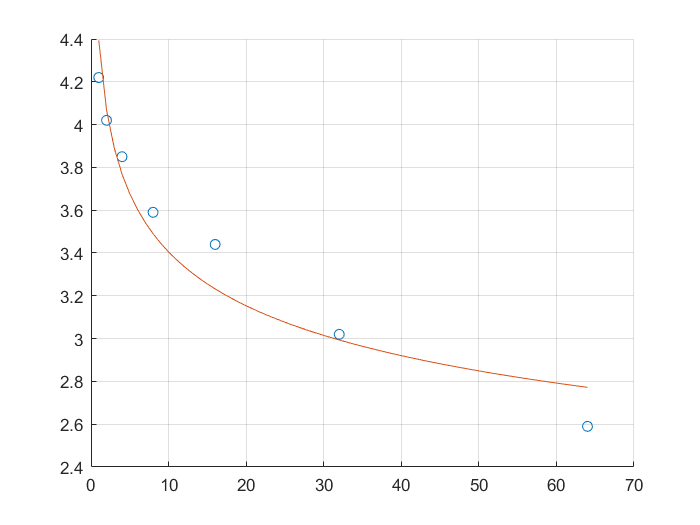

plot(1:64, exp(fit_equation(1:64, F_6, A_6)))
hold off
grid on

c_6 = exp(A_6(1))

c_6 = 4.3940

lambda_6 = A_6(2)

lambda_6 = -0.1107

得到$w=4.3940t^{-0.1107}$

**7. 原子弹爆炸的能量估计。 1945年7月16日， 美国在Las Alamos沙漠试爆了世界上第一颗原子弹。 两年之后， 美国政府首次公开了这次爆炸的录像带， 而其他数据和资料仍然不被外界所知。 物理学家G.I.Taylor通过研究录像带， 通过测量爆炸形成的“蘑菇云”的半径估计了爆炸所释放的能量。 他得到的估计值与若干年后正式公布的爆炸能量21kt相当接近 (1kt为1千吨TNT炸药的爆炸能量, **$$1 \text{ kt}=4.184\times 10^{12}$$** 焦耳)。 Taylor的想法是： 蘑菇云半径**$$r$$**与时间**$$t$$**, 爆炸能量**$$E$$**以及空气密度**$$\rho$$**有关， 在分析这几个量的单位后， 采用量纲分析法得到如下蘑菇云半径的近似表达式**

  
$$ $$
   r=\left(\frac{t^2E}{\rho}\right)^{\frac{1}{5}}
   $$$$


**   其中**$$r$$**, **$$t$$**, **$$E$$**的单位分别是米，毫秒和焦耳， 空气密度**$$\rho$$**取为1.25 kg/m**$$^3$$**.  请下载并读取数据文件`Taylor_bomb_energy.xlsx`, 根据蘑菇云半径随时间变化的数据估计**$$E$$**， 请用kt表示你的计算结果。**

解：

clear all; close all; clc
T_7 = xlsread('Taylor_bomb_energy.xlsx');
t_7 = T_7(:,1)'*0.001;
r_7 = T_7(:,2)';

将原式表示为$r^5=E\frac{t^2}{\rho}$，

对等号两边同时取对数可以得到$5\ln{r}-2\ln{t}+\ln{\rho}=\ln{E}$

以独立函数1进行拟合

F_7 = {@(t) 1};
A_7 = normal_equation(ones(size(t_7)), 5.*log(r_7) - 2.*log(t_7) + log(1.25), F_7);
E_7 = exp(A_7) / 4.184e12

E_7 = 20.6543

可以得到根据蘑菇云半径随时间变化的数据估计出的$E\approx20.6543kt$

*************************************************functions*********************************************************

normal_equation：法方程法线性最小二乘拟合

args：

    x：n维拟合数据自变量

    y：n维拟合数据应变量

    f：m个线性独立函数

output：

    A：m维独立函数的系数

function A = normal_equation(x, y, f)
    n = length(x);
    m = length(f);
    F = zeros(n ,m);
    for i = 1:m
        f_i = f{i};
        F(:, i) = f_i(x)';
    end
    A = F'*F \ F'*y';
end

fit_equation：与线性最小二乘拟合相配合使用，用于计算拟合后函数值的函数

args：

    x：需要拟合的数据

    f：m个线性独立函数

    A：m维独立函数的参数

output：

    y：拟合的输出

function y = fit_equation(x, f, A)
    y = zeros(size(x));
    for i = 1:length(f)
        f_i = f{i};
        y = y + A(i)*f_i(x);
    end
end

SSE：sum of squares due to error

args：

    y：函数值

    f：拟合值

output：

    SSE：残差

function SSE = cal_SSE(y, f)
    SSE = sum((y - f).^2);
end